syms ss;

g = 9.8;
M = 1; % kg
R = 3; % Ohm
L = 1; % H

y0 = 1;
i0 = sqrt(M*g*y0^2);

K = -2*i0/(M*y0^2*L);
denom = (ss+R/L)*(ss^2 - 2*i0^2/(M*y0^3));
G_s = K/denom;

% Inverse Laplace Transform
g_t = ilaplace(G_s)

$$g\_t = \frac{15\,\sqrt{2}\,\sinh\left(\frac{7\,\sqrt{2}\,\sqrt{5}\,t}{5}\right)}{53}-\frac{14\,\sqrt{5}\,\cosh\left(\frac{7\,\sqrt{2}\,\sqrt{5}\,t}{5}\right)}{53}+\frac{14\,\sqrt{5}\,{\mathrm{e}}^{-3\,t}}{53}$$

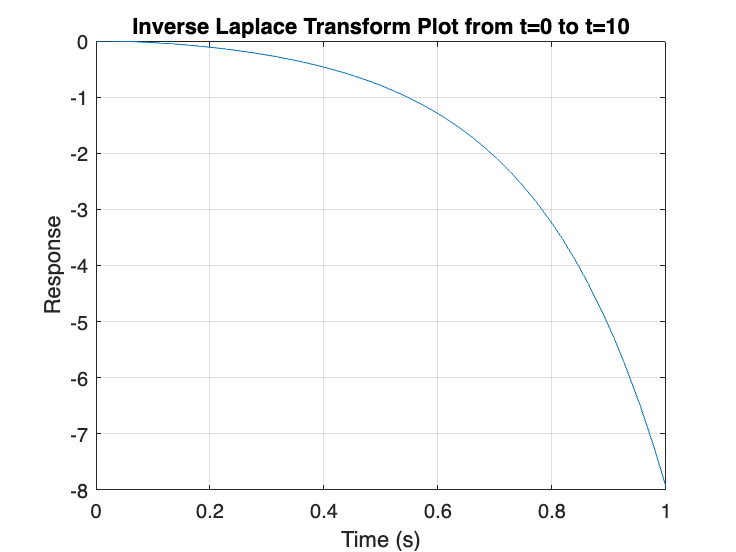


fplot(g_t, [0, 1]);
xlabel('Time (s)');
ylabel('Response');
title('Inverse Laplace Transform Plot from t=0 to t=10');
grid on;